# MXB226 Case Study Modelling an Electronic Component

## Full Storage

load full_storage;
%Solving using cholesky factorisation, then forward and backward substitution
tic;
[A_cholesky, FullStorageFlops] = cholesky(A, 0);
[temperatures, FullStorageFlops] = forward_substitution(A_cholesky', b, FullStorageFlops);
[temperatures, FullStorageFlops] = backward_substitution(A_cholesky, temperatures, FullStorageFlops);
Choleksy_Full_Storage_Runtime = toc;

Visualisating the Temperature from Full Storage

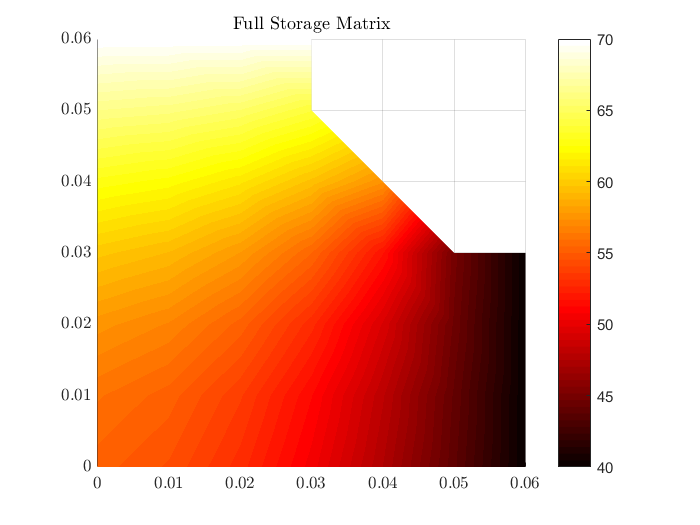

visualisation(temperatures, 'Full Storage Matrix')

## Packed Storage

load full_storage
%NOT CORRECT, NEED TO FIX FORWARD AND BACK SUBS
A_packed = packed_storage(A);
tic;
[a, PackedFlops] = Cholesky_Packed(A_packed, 0);
[temperatures, PackedFlops] = packed_forward_substitution(a, b, PackedFlops);
[temperatures, PackedFlops] = packed_backward_substitution(a, temperatures, PackedFlops);
Cholesky_Packed_Runtime = toc;

Visualisating the Temperature from Packed Storage

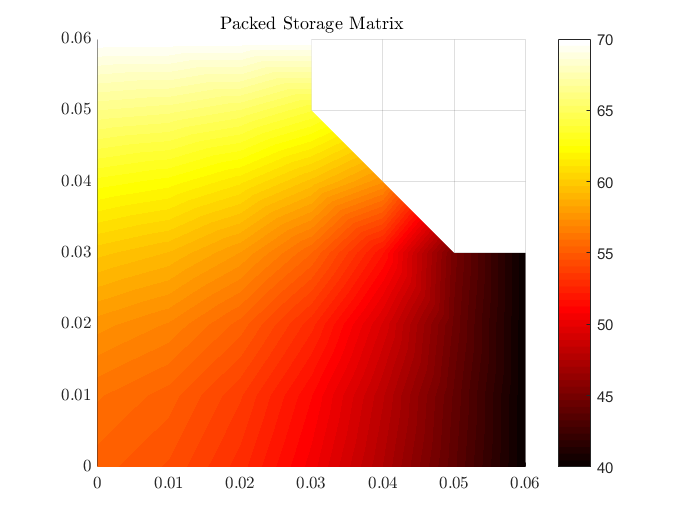

visualisation(temperatures, 'Packed Storage Matrix')

## Band Storage

%RCM Storage
load full_storage
%Create a new matrix to work with
A_RCM = A;
%create ordering vector
p= symrcm(A_RCM);
%order the A matrix and b vector according the RCM storage
A_RCM = A_RCM(p,p);
b_rcm = b(p);
reorder = reorder_vector(p);
%Create a band storage for A
A_band = band(A_RCM);
%Perform cholesky factorisation on the banded matrix
tic;
[G_Band_then_chol,BandFlops] = cholesky_band(A_band, 8, 0);

%solve with forward substitution and then backwards substitution

[temperatures, BandFlops] = banded_forward_substitution(G_Band_then_chol, b_rcm, BandFlops);
[temperatures, BandFlops] = banded_backward_substitution(G_Band_then_chol, temperatures, BandFlops);
temperatures = temperatures(reorder);
Choleksy_Band_Runtime = toc;
%Visualisating the Temperature from Band Storage

Visualise the temperatures

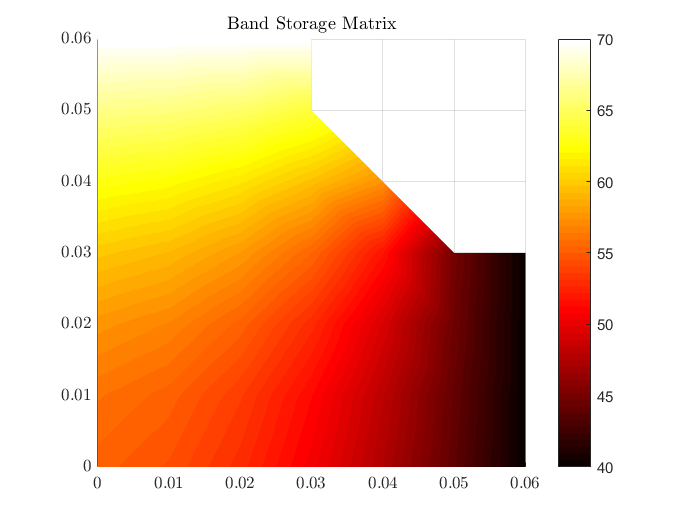

visualisation(temperatures, 'Band Storage Matrix')

## Sparse Storage

[A_sparse, b_sparse, reorder] = sparseStorage(A, b);

tic;
[A_AMD_cholesky, SparseFlops] = cholesky(A_sparse, 0);

%solve with forward substitution and then backwards substitution

[temperatures, SparseFlops] = forward_substitution(A_AMD_cholesky', b_sparse, SparseFlops);
[temperatures, SparseFlops] = backward_substitution(A_AMD_cholesky, temperatures, SparseFlops);
temperatures = temperatures(reorder);

Cholesky_Sparsed_Runtime = toc;

Visualisating the Temperature from Sparse Storage

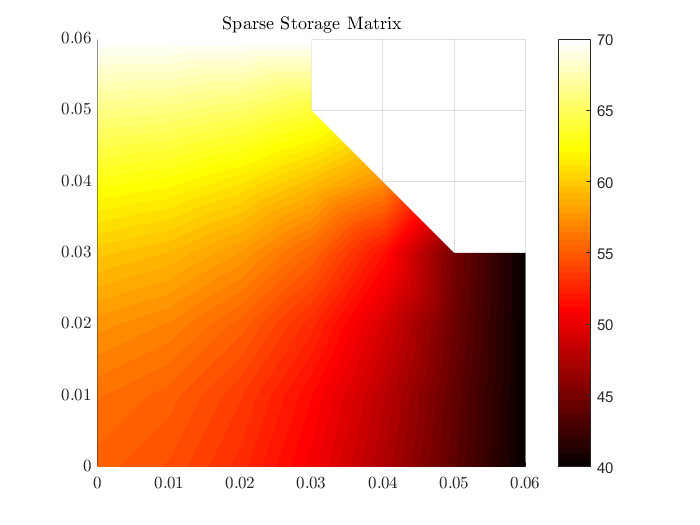

visualisation(temperatures, 'Sparse Storage Matrix')

## CSR Storage

clear rb;
[r,c,v] = find(A);
[r_sorted,order] = sort(r);
c = c(order);
v = v(order);

r_current = r_sorted(1);
count = 0;
rb = 1;

for i = 1:length(r_sorted)
    count = count + 1;
    if (r_sorted(i) ~= r_current)
        rb = [rb, count];
        r_current = r_sorted(i);
    end
end

% rb ends with nz + 1, where nz is the total number of nonzero elements in A.
rb = [rb, count + 1];

n = size(A, 1);
x0 = ones(n, 1)*10;
tol = 1e-5;
maxiters = 1000;

Solve CSR Using Jacobi Method

tic;
[temperatures, ~, jacobi_k, jacobi_res, JacobiFlops] = jacobi_CSR(rb, c', v', b, x0, tol, maxiters, 0);
Jacobi_Runtime = toc;

Visualisating the Temperature from Jacobi CSR Storage

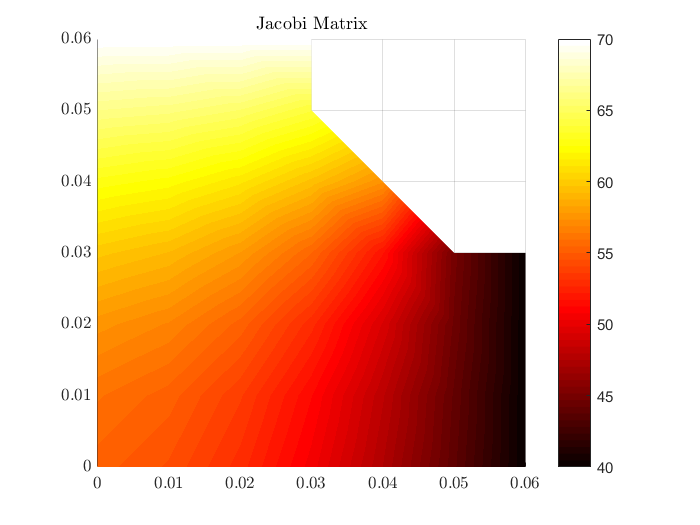

visualisation(temperatures, 'Jacobi Matrix')

Solve CSR Using Gauss Seidel Method

tic;
[temperatures, ~, gs_k, gs_res, GaussFlops] = gauss_seidel_CSR(rb, c', v', b, x0, tol, maxiters, 0);
Gauss_Seidel_Runtime = toc;

Visualisating the Temperature from Gauss Seidel CSR Storage

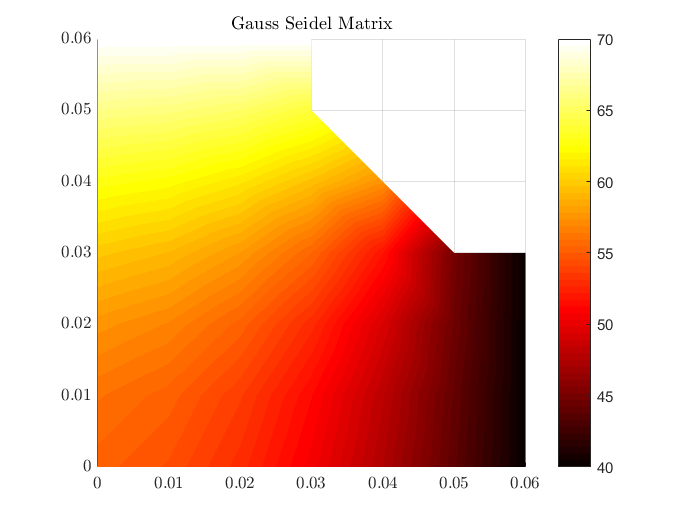

visualisation(temperatures, 'Gauss Seidel Matrix')

Solve CSR Using Conjugate Gradient Method

tic;
[temperatures, ~, conjugate_k, conjugate_res, ConjugateFlops] = conjugate_gradient_CSR(rb, c', v', b, x0, tol, maxiters, 0);
Conjugate_Gradient_Runtime = toc;

Visualisating the Temperature from Conjugate Gradient CSR Storage

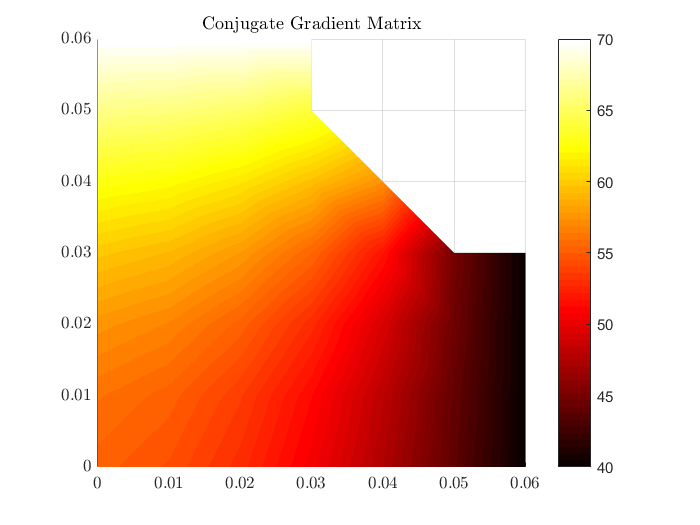

visualisation(temperatures, 'Conjugate Gradient Matrix')

Solve CSR Using SOR Method

D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);
T_J = - (D \ (L + U));
rhoT_J = max(abs(eig(T_J)));
w_opt = (2 /(1 + sqrt(1 - rhoT_J^2)));

tic;
[temperatures, ~, SOR_k, SOR_res, SORFlops] = sor_CSR(rb, c', v', b, x0, w_opt, tol, maxiters, 0);
SOR_Runtime = toc;

Visualisating the Temperature from SOR CSR Storage

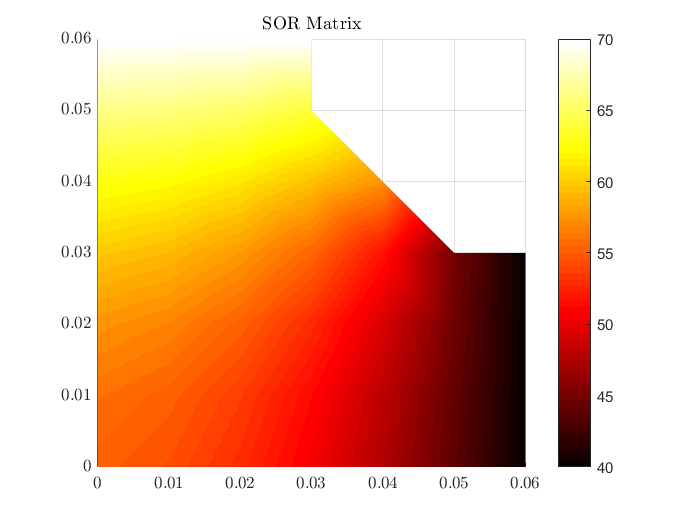

visualisation(temperatures, 'SOR Matrix')

## Efficiency Comparison

Bandwidth and level of fill-in for each different Node Ordering

%ffgdfh

Memory (for direct Methods), Iterations (for Iterative Methods), Runtime (Direct and Iterative), Floating Point Operations (direct and iterative).

%Memory
whos A b A_packed A_band A_sparse

  Name           Size             Bytes  Class     Attributes

  A             33x33              8712  double              
  A_band        33x7               1848  double              
  A_packed       1x561             4488  double              
  A_sparse      33x33              2528  double    sparse    
  b             33x1                264  double              



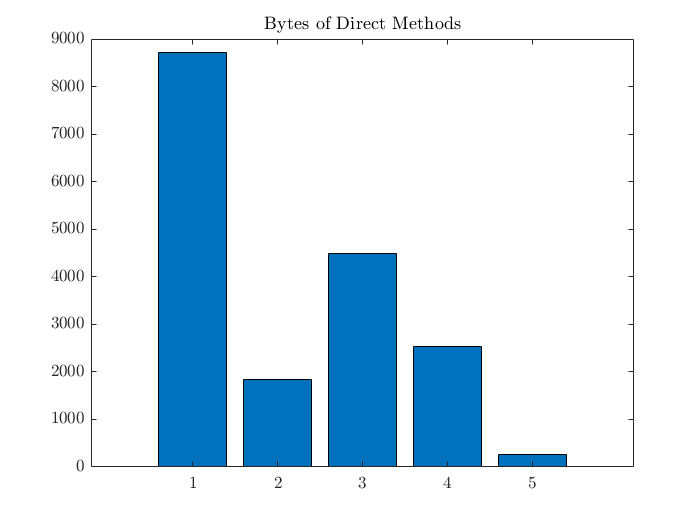

Direct_Method_Bytes = [8712, 1848, 4488, 2528, 264];
figure
bar(Direct_Method_Bytes)
title('Bytes of Direct Methods', 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')

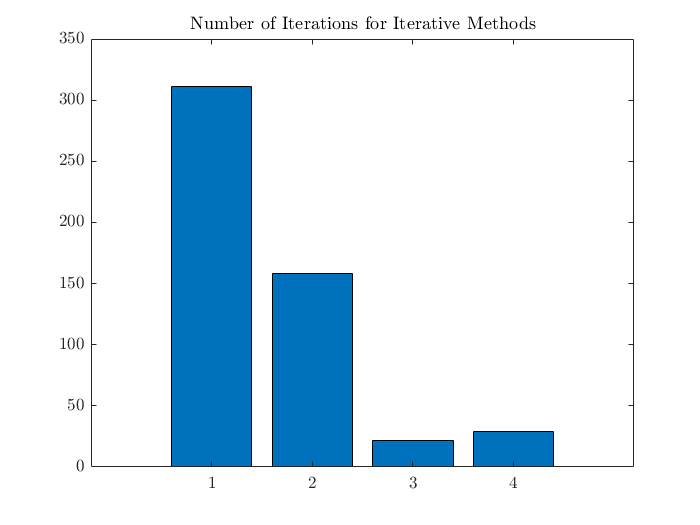


%Iterations
NumberIterations = [jacobi_k, gs_k, conjugate_k, SOR_k];
figure
bar(NumberIterations)
title('Number of Iterations for Iterative Methods', 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')

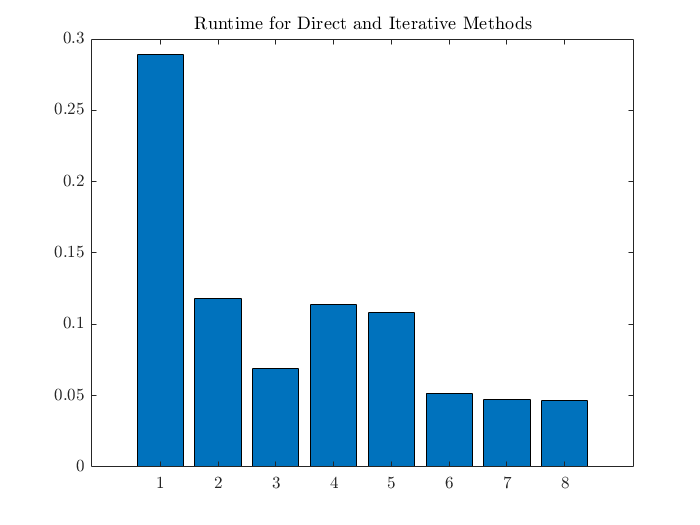


%Runtime
Runtime = [Choleksy_Full_Storage_Runtime, Cholesky_Packed_Runtime, Choleksy_Band_Runtime, ...
    Cholesky_Sparsed_Runtime, Jacobi_Runtime, Gauss_Seidel_Runtime, Conjugate_Gradient_Runtime, ...
    SOR_Runtime];
% name = {'Cholekey Full Storage'; 'Cholesky Packed Storage'; 'Choleksy Band Storage'; ....
%     'Cholesky Sparsed Storage'; 'Jacobi CSR Storage'; 'Gauss Seidel CSR Storage'; ...
%     'Conjugate Gradient CSR Storage'; 'SOR CSR Storage' };

figure
bar(Runtime)
title('Runtime for Direct and Iterative Methods', 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')

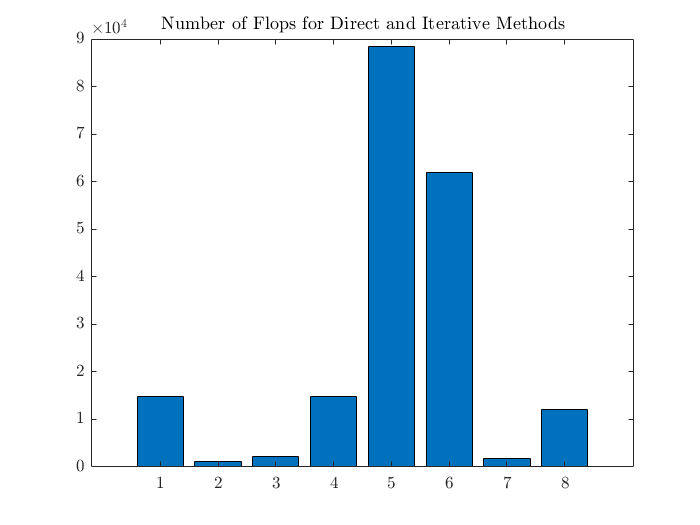

%set(gca,'xticklabel',name)

%Floating Point Operations
NumberFlops = [FullStorageFlops; PackedFlops; BandFlops; SparseFlops; ...
    JacobiFlops; GaussFlops; ConjugateFlops; SORFlops];
figure
bar(NumberFlops)
title('Number of Flops for Direct and Iterative Methods', 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')

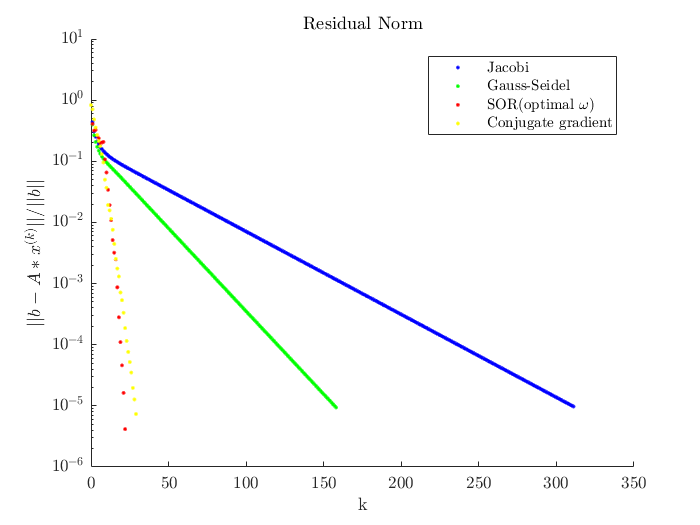


figure
hold on
set(gca, 'Yscale', 'log');
ylim([1e-6 10]);
plot(0:jacobi_k, jacobi_res, 'b.');
plot(0:gs_k, gs_res, 'g.');
plot(0:conjugate_k, conjugate_res, 'r.');
plot(0:SOR_k, SOR_res, 'y.');
title('Residual Norm', 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')

lgd = legend('Jacobi', 'Gauss-Seidel', 'SOR(optimal $\omega$)', 'Conjugate gradient');
lgd.Interpreter = 'latex';

ylabel('$||b-A*x^{(k)}|| / ||b||$', 'Interpreter','latex')
xlabel('k', 'Interpreter','latex')

Tolerance that is required for the iterative method to produce a solution that is visually indistinguishable from that produced by the direct methods.

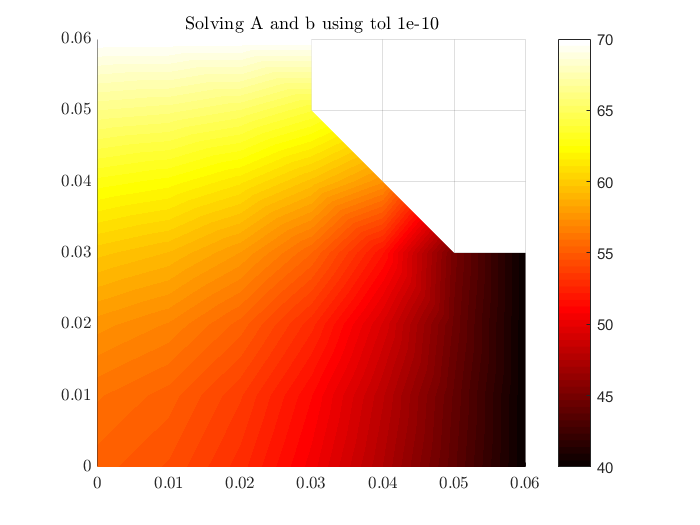

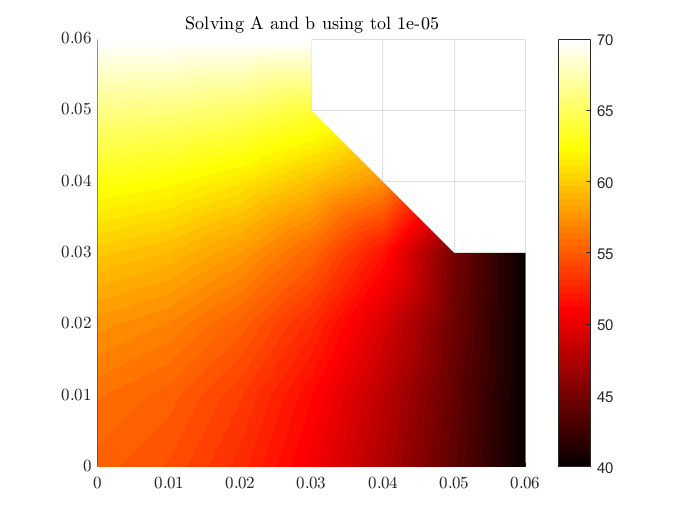

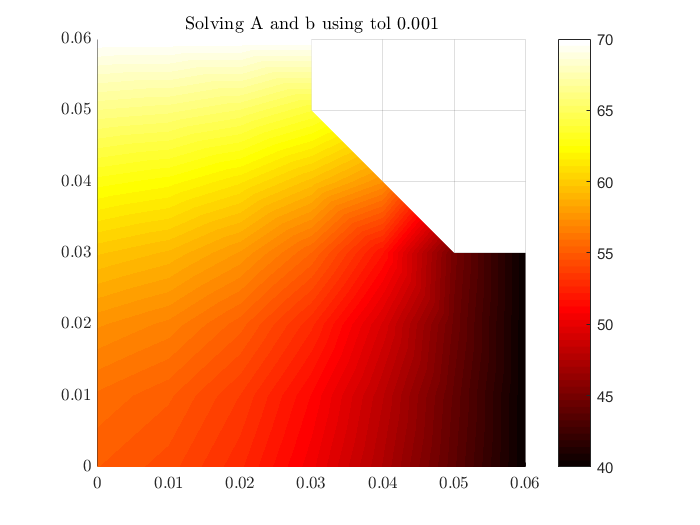

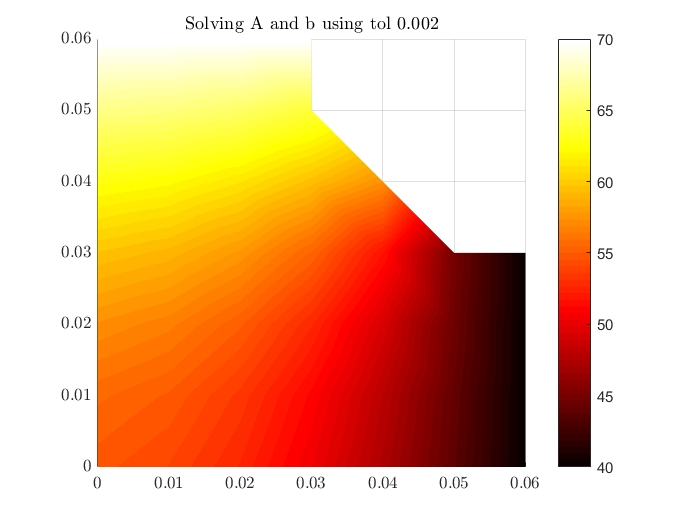

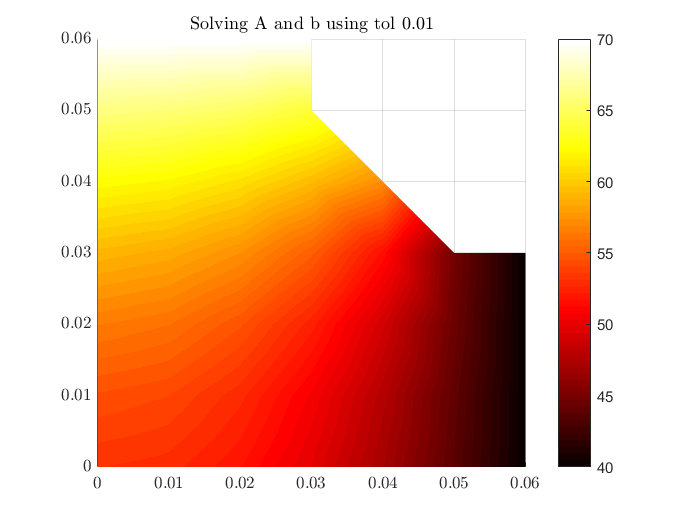

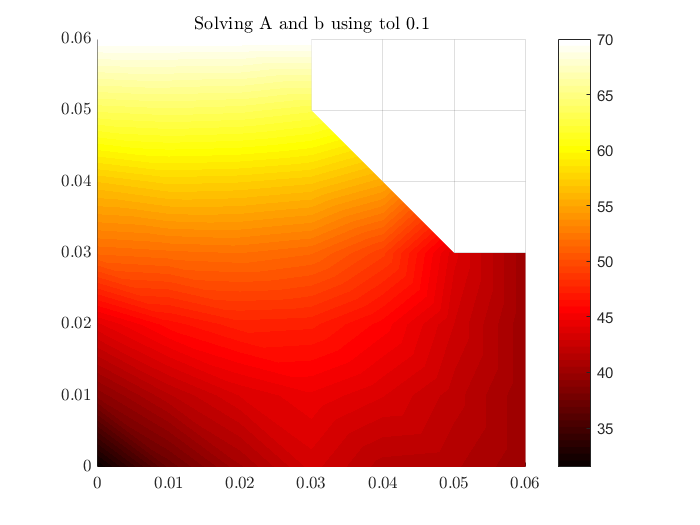

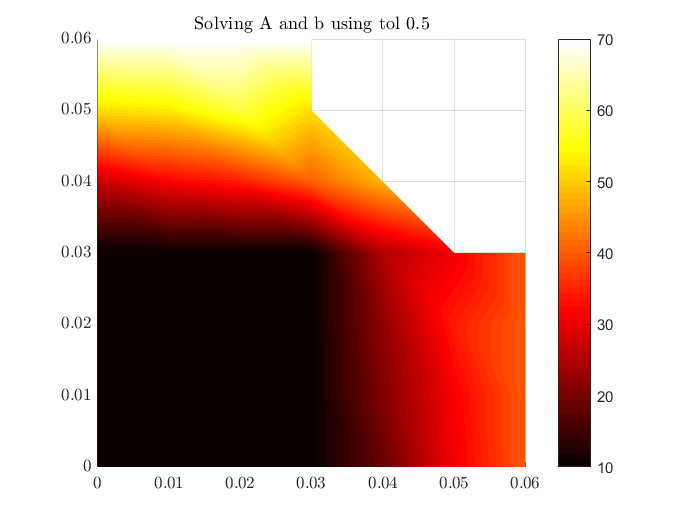

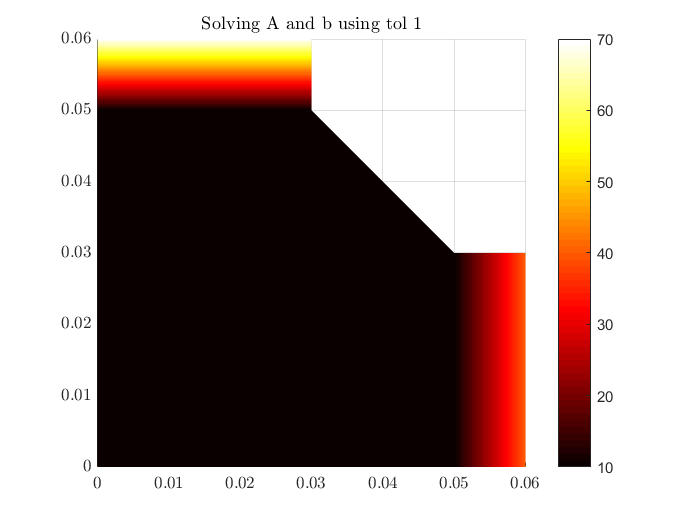

tolVec = [1e-10, 1e-5, 1e-3, 2e-3, 1e-2, 1e-1, 0.5, 1];
[~,n] = size(tolVec);

for i = 1:n
    [temperatures, ~, ~, ~, ~] = sor_CSR(rb, c', v', b, x0, w_opt, tolVec(i), maxiters, 0);
    graphTitle = ['Solving A and b using tol ', num2str(tolVec(i)), ''];
    visualisation(temperatures, graphTitle)
end

Effect of w on the rate of convergence of the SOR method.

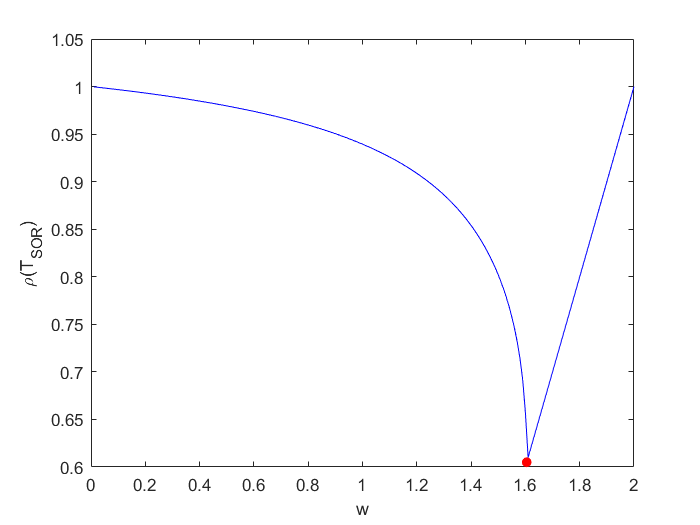

D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);
T_J = - (D \ (L + U));
rhoT_J = max(abs(eig(T_J)));
w_opt = (2 /(1 + sqrt(1 - rhoT_J^2)));
T_SOR_opt = (D/w_opt + L) \ ((1-w_opt)/w_opt * D - U);
rhoT_SOR_opt = max(abs(eig(T_SOR_opt)));

wVec = linspace(1e-2,2,200);
rhoT_SOR = zeros(1,200);

for i = 1:200
    w = wVec(i);
    T_SOR = (D/w + L) \ ((1-w)/w * D - U);
    rhoT_SOR(i) = max(abs(eig(T_SOR)));
end

figure;
plot(wVec, rhoT_SOR, 'b')
hold on
plot(w_opt, rhoT_SOR_opt,'r.','Markersize',20);
ylabel('\rho(T_{SOR})')
xlabel('w')

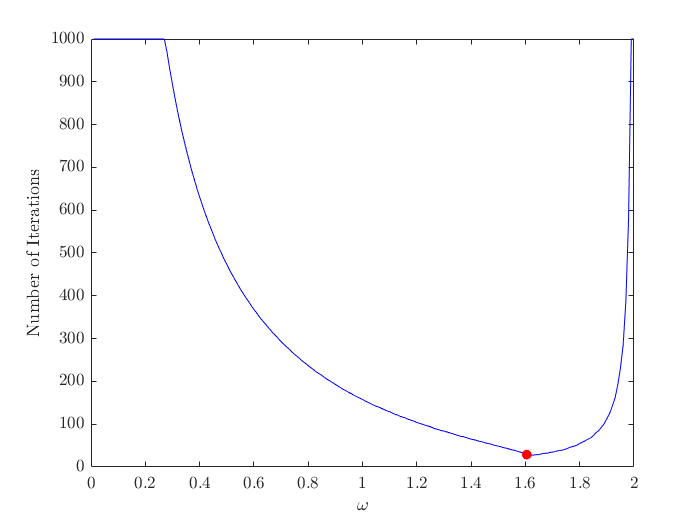


kVec = zeros(1,200);
[~, ~, k_opt, ~, ~] = sor_CSR(rb, c', v', b, x0, w_opt, tol, maxiters, 0);

for i = 1:200
    [~, ~, kVec(i), ~, ~] = sor_CSR(rb, c', v', b, x0, wVec(i), tol, maxiters, 0);
end

figure;
plot(wVec, kVec, 'b')
hold on
plot(w_opt, k_opt,'r.','Markersize',20);
ylabel('Number of Iterations', 'Interpreter','latex')
xlabel('$\omega$', 'Interpreter','latex')
set(gca,'TickLabelInterpreter','latex')